# Introduction to Functions

## Why Functions?

Programs so far...

- Procedural: Step-by-step

- Structured: Flow control and common variable *scope* (AKA MATLAB Workspace)

### Usability

#### Reuse

- Write once, use everywhere

- Don't repeat yourself (DRY)

Example: [https://github.com/bsb808/frlbox/tree/master/alvinxybox](https://github.com/bsb808/frlbox/tree/master/alvinxybox) 

#### Testing and Debugging

Functions are easier to test in isolation, making it simpler to verify correctness and debug issues.

Example after we discuss *local functions*

### Complexity Management

#### Modularity: Breaking a problem into manageable parts.

Rule of Modularity: Write simple parts connected by clean interfaces.

*The only way to write complex software that won't fall on its face is to hold its global complexity down — to build it out of simple parts connected by well-defined interfaces, so that most problems are local and you can have some hope of upgrading a part without breaking the whole.*

#### Abstraction: Hiding the details and designing the exposing an interface

*Rule of Separation: Separate policy from mechanism; separate interfaces from engines*

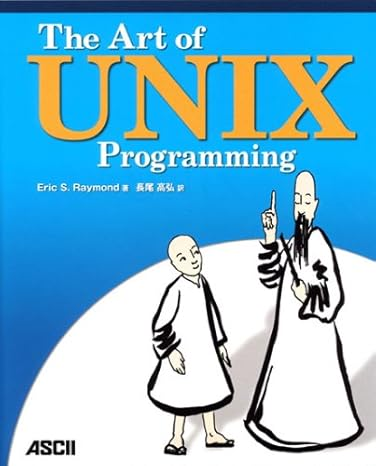

# Implementing Functions in MATLAB

- **Primary functions:** A function in its own m-file

- **Local functions**: A function within a script

- **Anonymous functions:** A one-line function without a name, used for passing functions as inputs.  (Covered later.)

## Primary Functions

- A function in its own m-file

- The name of the m-file and the name of the function are the same!

Documentation

- Signature

- Description

- Input arguments

- Output values

- See also

edit mean
help mean

### Path

To use the function it needs to be in the MATLAB *path*.  The simplest way to do this is to have the the function in the *current working directory* - as displayed in the Command Window

edit rr2dd
help rr2dd

d = rr2dd(pi/2)

### Scope

The variables within the function are in their own workspace.  They can't be accessed by other functions or by the Command Window's base workspace.

From the base workspace we can't access the variables from our functions `bearing` and `rr2dd`.

whos

## Local Functions

- Functions defined within a (live) script.

- It’s only visible to the code in that same file—think of it as a helper function.

*Before R2024a: Local functions in scripts must be defined at the end of the file, after the last line of script code.*

We can implement the same code from the primary function in `rr2dd.m` as a local function:

function d = radians2degrees(r)
    % d = radians2degrees(r)
    %
    % Convert angle from radians to degrees.
    %
    % Input arguments:
    % * r: angle in radians
    %
    % Output arguments:
    % * d: angle in degrees

    d = r*180.0/pi;
end

We can cal the local function like this...

theta = radians2degrees(pi/2)

## Variable Scope

**Variable scope** defines where a variable exists and can be accessed in a program. In MATLAB, variables created inside a function are separate from those in the workspace, while variables in a script share the same workspace as the Command Window.

For example, from the live script, we cannot set the value of `r` used within the function...

r = 0;
theta = radians2degrees(pi/2)

Similarly, the variable `d` from the function cannot be accessed from the live script

d

### Debugging

[MATLAB debugger](https://www.mathworks.com/help/matlab/matlab_prog/debugging-process-and-features.html)

- Set brakepionts   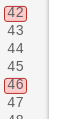

- Examine values in the scope of the function    

- Step (dbstep), Step-Into (dbstep in/out), Continue (dbcont)        

### Testing and the Debugger

Here is a function for calculating the compass bearing to a point.

function b_deg = bearing(x, y)
    % Calculate the compass bearing in degrees from the origin to point x,
    % y, in range [0 360].
    a = atan(y/x);
    b_rad = mod(pi/2-a, 2*pi);
    b_deg = b_rad*180.0/pi;
end

A **unit test** is a small, isolated test that verifies the functionality of a specific piece of code, typically a single function or method, to ensure it behaves as expected under various conditions.

% Test 1: First quadrant
q1 = bearing(1, 2);
disp(['Test 1 - Expected: [0 90], Received: ', num2str(q1)])

% Test 2: Second quadrant
q2 = bearing(-1, 1);
disp(['Test 2 - Expected: [270 360], Received: ', num2str(q2)])

% Test 3: Third
q3 = bearing(-4, -2);
disp(['Test 3 - Expected: [180 270], Received: ', num2str(q3)])

### Number of arguments and defaults

The variable `nargin` contains the number of arguments, which we can use to set default values.

function [new_m, new_pg] = update_bikes(m, pg, rate_m_to_pg, rate_pg_to_m)
    % [new_m, new_pg] = update_bikes(m, pg, rate_m_to_pg, rate_pg_to_m)
    % Input arguments
    % - m: number of bikes in Monterey on day k
    % - pg: number of bikes in Pacific Grove on day k
    % - rate_m_to_pg: daily fraction of bikes in Monterey moved to PG.
    % - rate_pg_to_m: daily fraction of bikes in PG moved to Monterey.
    % Output variables
    % - new_m: bikes in Monterey on day k+1
    % - new_pg: bikes in PG on day k+1
    
    % Set defaults
    if nargin < 4
        rate_pg_to_m = 0.03;
    end
    if nargin < 3
        rate_m_to_pg = 0.05;
    end

    m_to_pg = round(0.05*m) - round(0.03*pg);
    new_m = m - m_to_pg;
    new_pg = pg + m_to_pg;
end

% Script
n = 20;
mm = [100 zeros(1,n-1)];
ppg = [100 zeros(1,n-1)];
for ii = 2:n
    % Move bikes
    [m, pg] = update_bikes(mm(ii-1), ppg(ii-1));
    mm(ii) = m;
    ppg(ii) = pg;
end
figure
clf()
plot(mm, 'rs', 'DisplayName', "Monterey");
hold on
plot(ppg, 'bo', 'DisplayName', "Pacific Grove")
xlabel('Time steps [days]')
ylabel('Inventory in town [bikes]')
grid('on')
legend('Location','NorthWest')